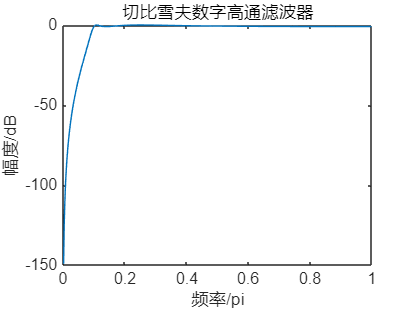

clear,clc;  % 清除工作区和命令窗口

% 设计指标
fs=40;      % 阻带截止频率
fp=200;     % 通带截止频率
ft=20*fp;   % 采样频率
rs=60;      % 阻带最小衰减(dB)
rp=1;       % 通带最大波纹(dB)

% 频率归一化（直接归一化到 [0,1]）
wp=fp/(ft/2);    % 将通带频率归一化
ws=fs/(ft/2);    % 将阻带频率归一化

% 直接设计数字切比雪夫高通滤波器
[N,wn]=cheb1ord(wp,ws,rp,rs);           % 计算滤波器阶数和截止频率
[B,A]=cheby1(N,rp,wn,'high');           % 直接设计数字高通滤波器

% 计算频率响应
[H,w]=freqz(B,A);                        % 计算数字滤波器的频率响应
w=w/pi;                                  % 将频率归一化

% 绘制幅频特性图
figure(1);
plot(w,20*log10(abs(H)));                % 绘制幅频响应（单位：dB）
xlim([0, 1])                             % 设置x轴范围
xlabel('频率/pi');ylabel('幅度/dB');
title('切比雪夫数字高通滤波器');

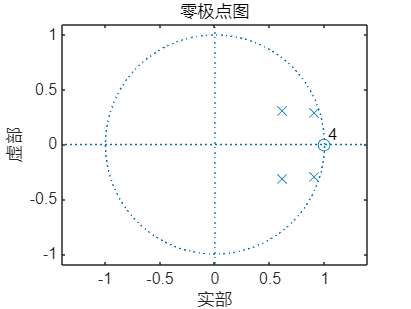


% 绘制零极点图
figure(2)
zplane(B,A);                             % 绘制零极点分布图
title('零极点图');